## Objem válce jako funkce úhlu

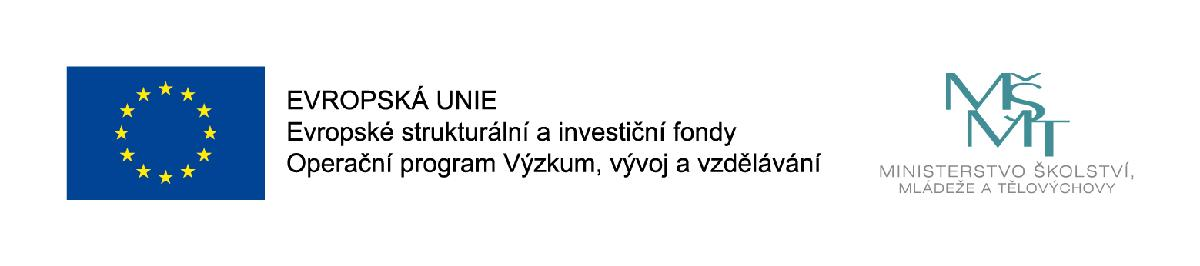

#### prof. Ing. Josef ŠTĚTINA, Ph.D. / Vysoké učení technické v Brně

#### email: [josef.stetina@vutbr.cz](mailto:josef.stetina@vutbr.cz)

#### www: [http://termomechanika.online/](http://termomechanika.online/)

$V_{ZM}   \left[cm^3\right]$         zdvihový objem motoru

**V****Z**** [cm****3****]:**zdvihový objem válce

**i: **počet válců

**V****k**** [cm****3****]:**kompresní objem válce

**V****max** **[cm****3****]:**kompresní objem válce

**V****min** **[cm****3****]:**kompresní objem válce

**D [cm] **: vrtání válce

**Z [cm]:**zdvih pístu

**L [cm]:**délka ojnice (střed čepů)

**R=Z/2 [cm]:**zalomení klikového h.

**E [cm]:**vyosení (většinou 0)

$\phi [°]$            otočení klikového hřídele

**e**** [ ]**: komprese (kompresní poměr)

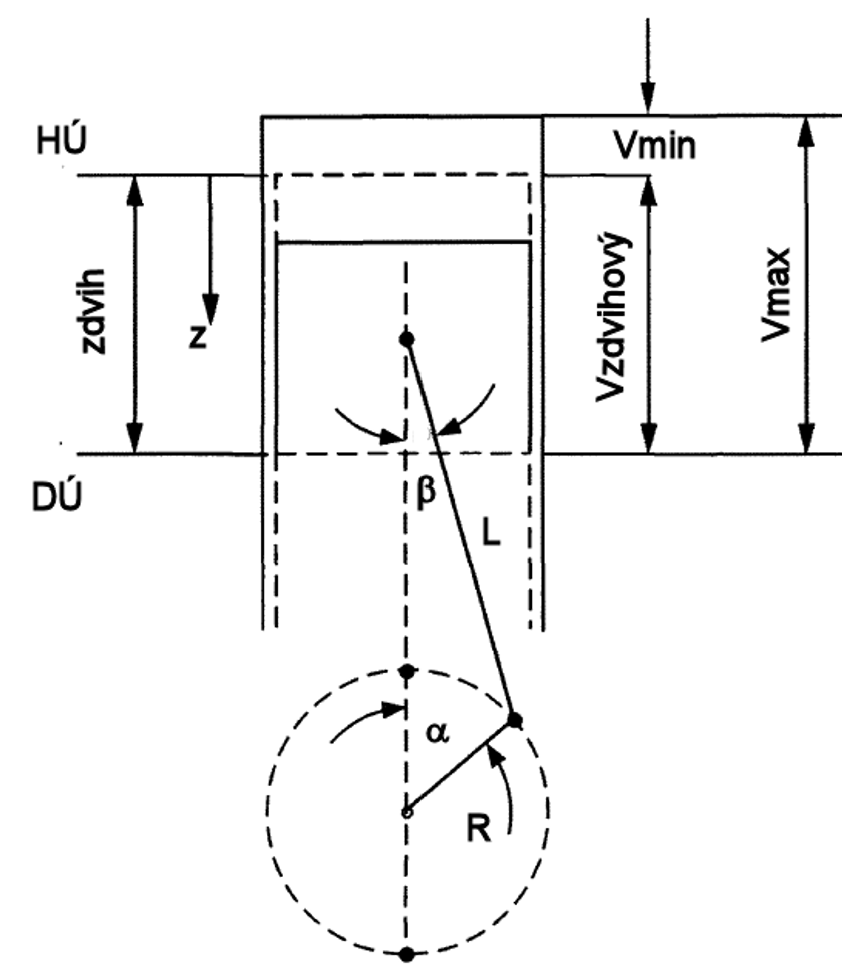


$$\[{V_Z} = \frac{{\pi {D^2}}}{4}Z\]$$



$$\[\varepsilon  = \frac{{{V_{MAX}}}}{{{V_{MIN}}}} = \frac{{{V_Z} + {V_K}}}{{{V_K}}}\]$$


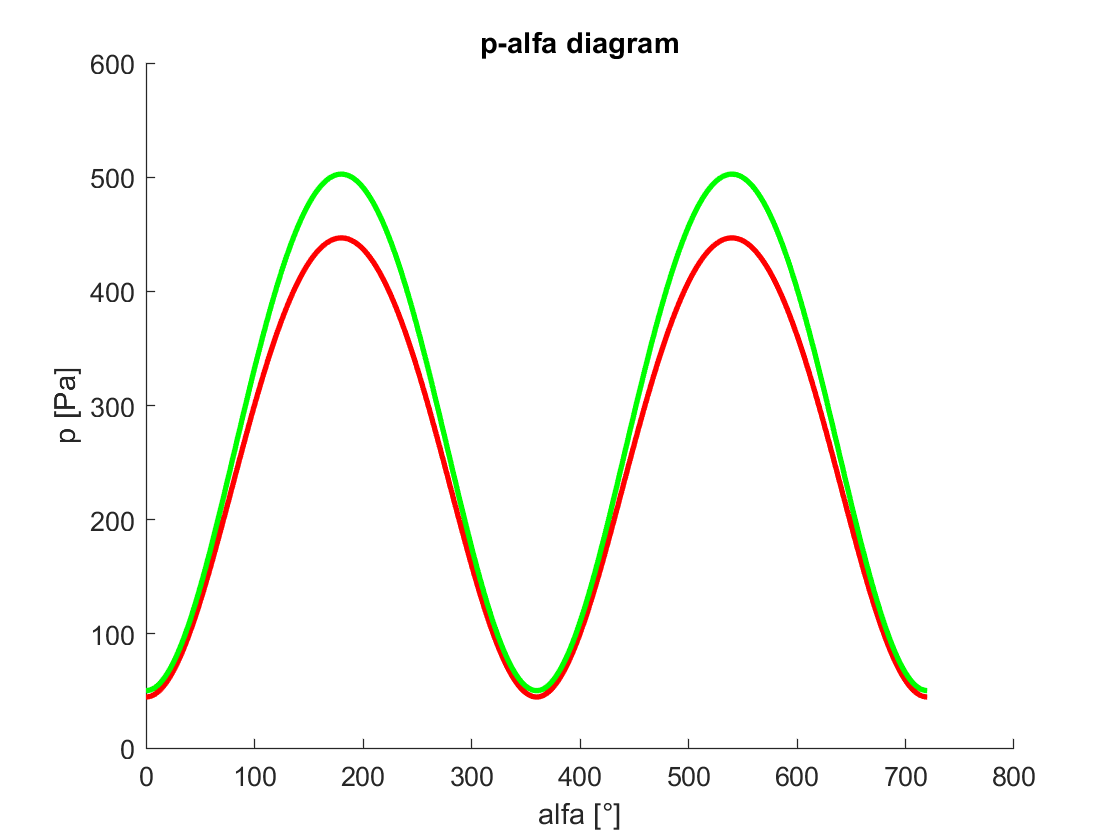

zdvih = 80;
vrtani = 80;
ojnice = 200;
vyos = 0;
komprese = 10;
[v1, vln1, alfa] = VolumeAlfa(zdvih, vrtani, ojnice, vyos, komprese);
komprese = 10;
[v2, vln2, alfa] = VolumeAlfa(zdvih+10, vrtani, ojnice+100, vyos, komprese);
komprese = 10;
[v3, vln3, alfa] = VolumeAlfa(zdvih, vrtani, ojnice, vyos, komprese);



% Vykreslení diagramu
figure;
title('Objem-úuhel')
xlabel('\phi Úhel otočení klikového hřídele [°]')
ylabel('p [Pa]')   
hold on;
plot(alfa,v1,'r-','linewidth',2);
plot(alfa,v2,'g-','linewidth',2);
hold off;

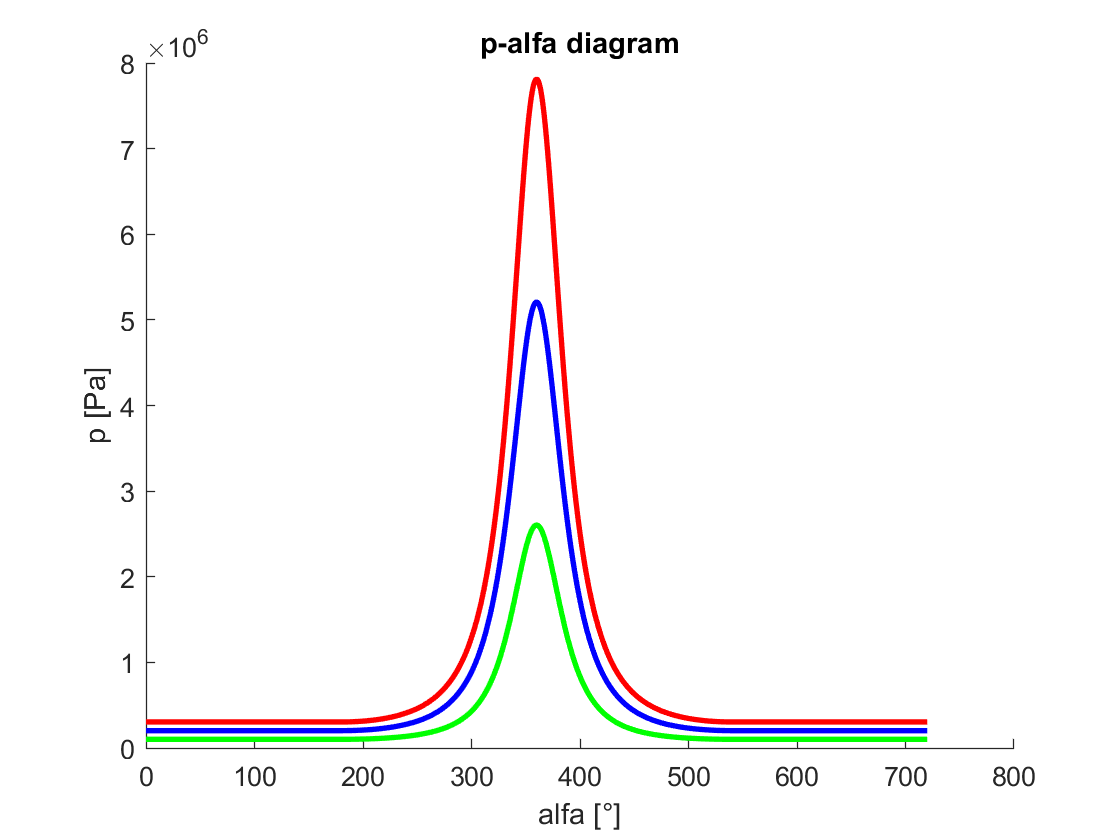




pb = 101325.0;  % Baropetrický tlak Pa
kappa1 = 1.41;    % vzduch
kappa2 = 1.41;    % vzduch

%Vv1 = linspace(V1,V2,180);
pv2 = zeros([1,721]);
Tv2 = zeros([1,721]);

pv2 = zeros([1,721]);
Tv2 = zeros([1,721]);

pv3 = zeros([1,721]);
Tv3 = zeros([1,721]);

%Sv1 = zeros([1,180]);
r = 287.0;
%m1 = pb * vd /10^6 /r /300.0

for i=1:180
  pv1(i) = pb;
  Tv1(i) = 300.0;
  pv2(i) = pb*2;
  Tv2(i) = 300.0;
  pv3(i) = pb*3;
  Tv3(i) = 300.0;
end;  

for i=181:361
  pv1(i) = pv1(i-1)*v1(i-1)^kappa1/v1(i)^kappa1;
  Tv1(i) = Tv1(i-1)*(pv1(i)/pv1(i-1))^((kappa1-1)/kappa1);
  pv2(i) = pv2(i-1)*v2(i-1)^kappa1/v2(i)^kappa1;
  Tv2(i) = Tv2(i-1)*(pv2(i)/pv2(i-1))^((kappa1-1)/kappa1);
  pv3(i) = pv3(i-1)*v3(i-1)^kappa1/v3(i)^kappa1;
  Tv3(i) = Tv3(i-1)*(pv3(i)/pv3(i-1))^((kappa1-1)/kappa1);
  %Sv1(i)=m1*cp*log(Tv1(i))-m1*r*log(pv1(i));
end

for i=361:541
  pv1(i) = pv1(i-1)*v1(i-1)^kappa2/v1(i)^kappa2;
  Tv1(i) = Tv1(i-1)*(pv1(i)/pv1(i-1))^((kappa2-1)/kappa2);  
  pv2(i) = pv2(i-1)*v2(i-1)^kappa2/v2(i)^kappa2;
  Tv2(i) = Tv2(i-1)*(pv2(i)/pv2(i-1))^((kappa2-1)/kappa2);  
  pv3(i) = pv3(i-1)*v3(i-1)^kappa2/v3(i)^kappa2;
  Tv3(i) = Tv3(i-1)*(pv3(i)/pv3(i-1))^((kappa2-1)/kappa2);  
%  Tv(i) = pv(i) * v(i)/10^6 / (r * m1);
  %Sv1(i)=m1*cp*log(Tv1(i))-m1*r*log(pv1(i));
end

for i=541:721
  pv1(i) = pv1(541);
  Tv1(i) = Tv1(541);
  pv2(i) = pv2(541);
  Tv2(i) = Tv2(541);
  pv3(i) = pv3(541);
  Tv3(i) = Tv3(541);
end;  


 % Vykreslení diagramu
figure;
title('p-alfa diagram')
xlabel('alfa [°]')
ylabel('p [Pa]')   
hold on;
plot(alfa,pv1,'g-','linewidth',2);
plot(alfa,pv2,'b-','linewidth',2);
plot(alfa,pv3,'r-','linewidth',2);
hold off;

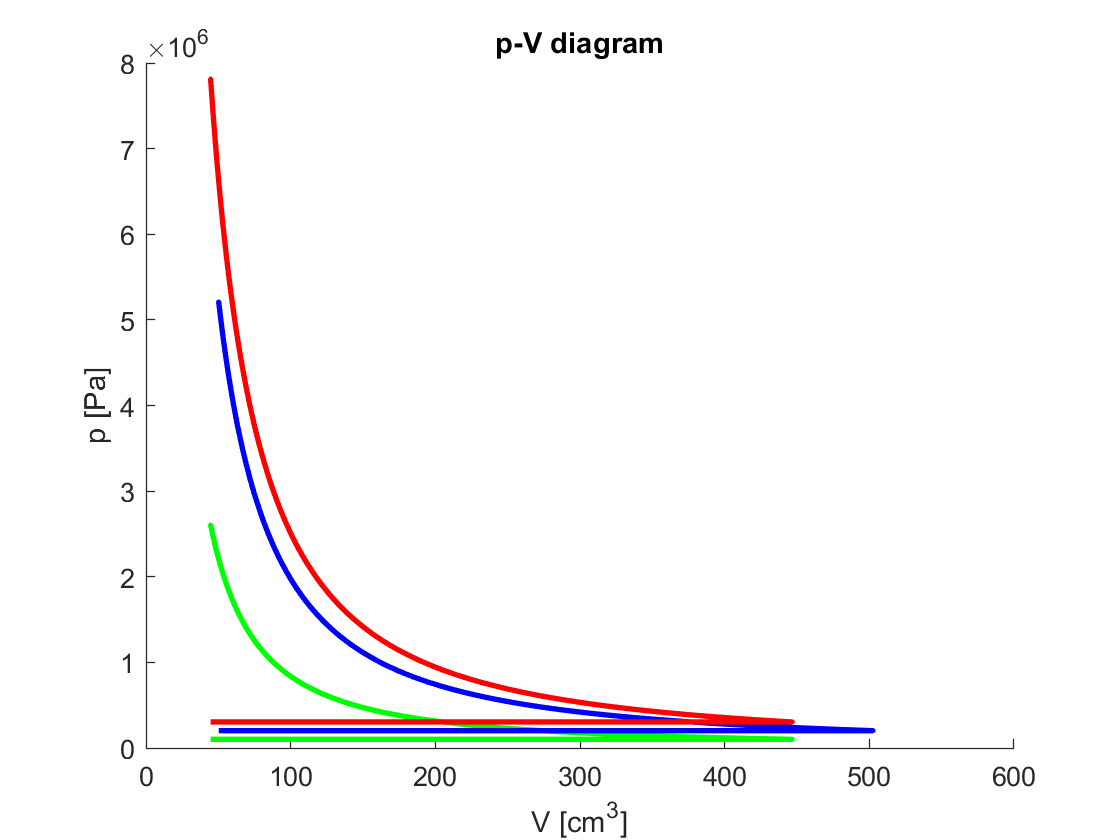


figure;
hold on;
title('p-V diagram')
xlabel('V [cm^3]')
ylabel('p [Pa]')   
plot(v1,pv1,'g-','linewidth',2);
plot(v2,pv2,'b-','linewidth',2);
plot(v3,pv3,'r-','linewidth',2);
hold off;

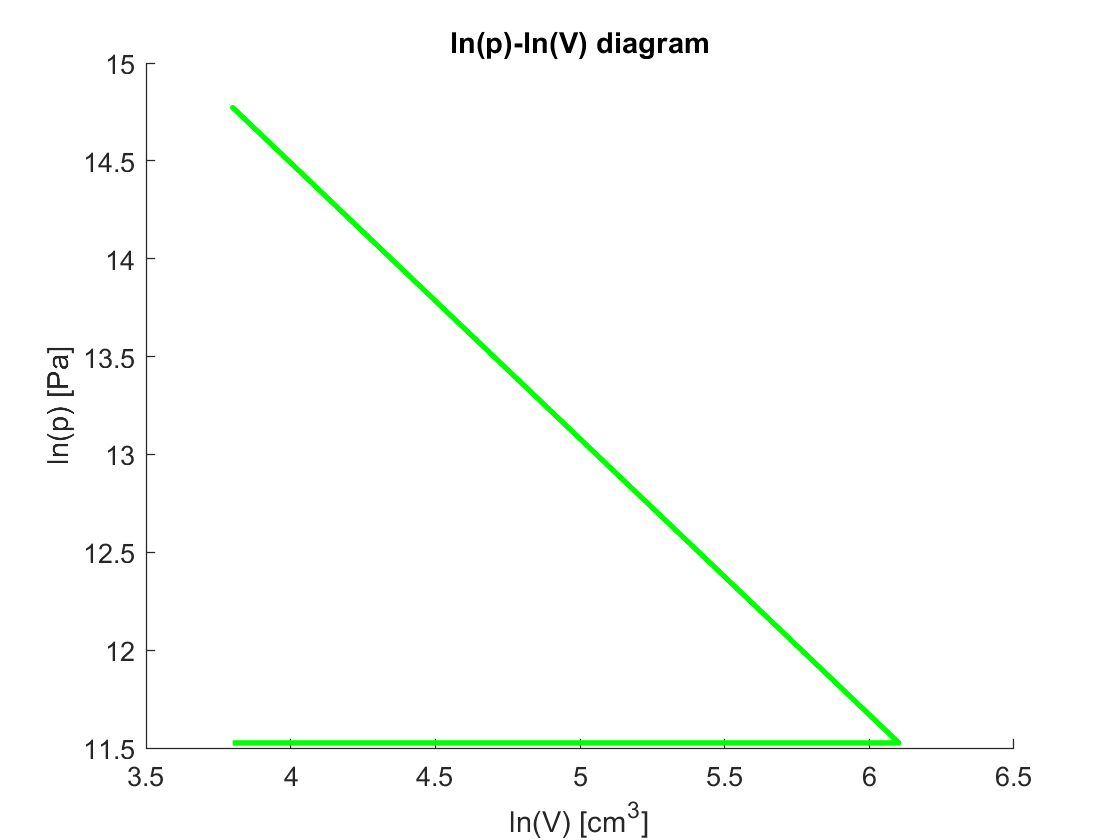


figure;
hold on;
title('ln(p)-ln(V) diagram')
xlabel('ln(V) [cm^3]')
ylabel('ln(p) [Pa]')   
plot(vln1,log(pv1),'g-','linewidth',2);
hold off;

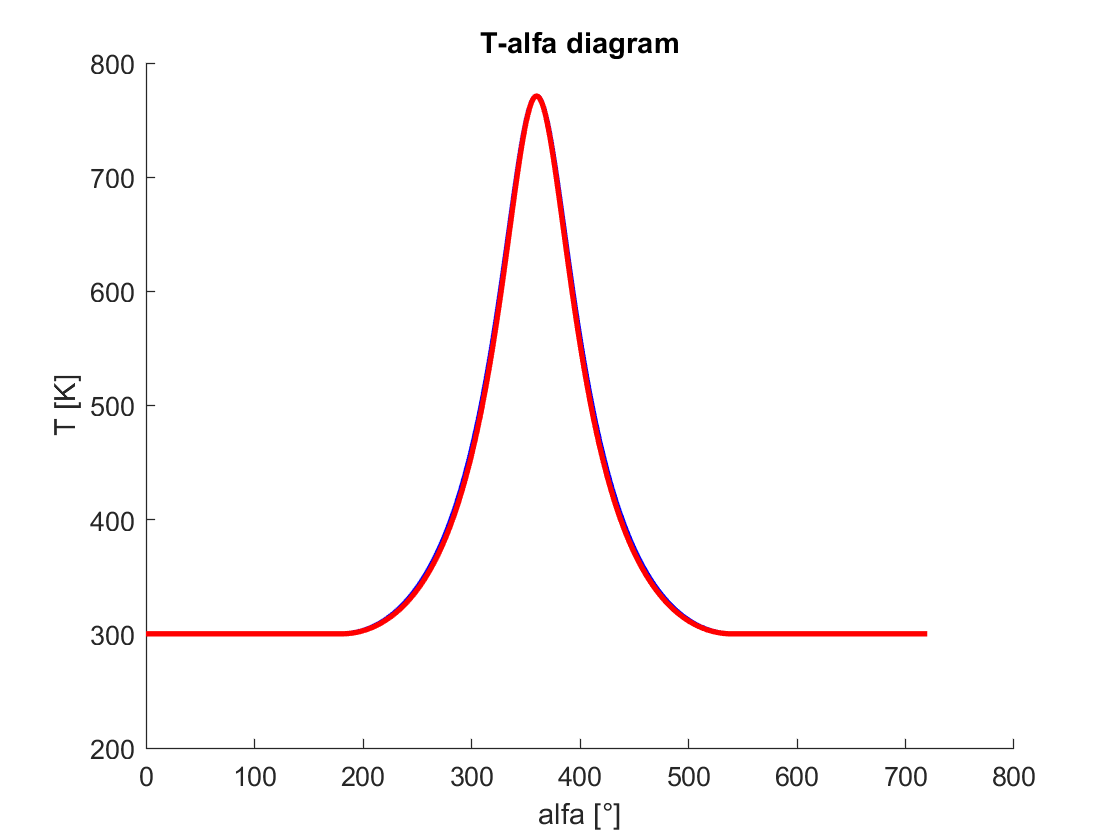


figure;
hold on;
title('T-alfa diagram')
xlabel('alfa [°]')
ylabel('T [K]')   
plot(alfa,Tv1,'g-','linewidth',2);
plot(alfa,Tv2,'b-','linewidth',2);
plot(alfa,Tv3,'r-','linewidth',2);
hold off;

## Interní funkce pro výpočet objemu jako funkce otočení klikového hřídele

function  [v, vln, alfa] = VolumeAlfa(zdvih, vrtani, ojnice, vyos, komprese)
% Výpočet objemu

%zdvih = 80;
%vrtani = 80;
%ojnice = 200;
%vyos = 0.0;
%deltahu = 0.0;
%komprese = 10.0;
step = 1.0;
deltahu = 0.0;

r = zdvih/20.0;  % polomer kliky
d = vrtani/10.0; %
l = ojnice/10.0; % delka ojnice
e = vyos/10.0;   % vyoseni klikoveho mechanismu
vzd = pi * d * d / 2.0 * r;    % zdvihovy objem valce 

deltaalrad = step * pi/180.0;   % deleni v radianech
n=round(360/step);             % {polovicni pocet hodnot 1 cyklu}
vd1 = vzd/2.0;
vd2 = 0.5 * vzd / r;

deltahur = deltahu * pi / 180.0;  % odchylka HU v rad.
vd = vzd*(1/(komprese-1)+0.5/r*sqrt((r+l)*(r+l)-e*e));
vr1 =vd-vd1*cos(-deltahur)-vd2*sqrt(l*l-(r*sin(-deltahur)-e)^2);
v(1) = vr1;  
vln(1) = log(vr1);
alfa(1) = 0.0;

for i=1:n
  vr1 =vd-vd1*cos(i*deltaalrad-deltahur)-vd2*sqrt(l*l-(r*sin(i*deltaalrad-deltahur)-e)^2);
  v(i+1)   = vr1;
  v(i+n+1) = vr1;
  vln(i+1)   = log(vr1);
  vln(i+n+1) = log(vr1);
  alfa(i+1) = i*step; 
  alfa(i+n+1) = (i+n)*step; 
end
end